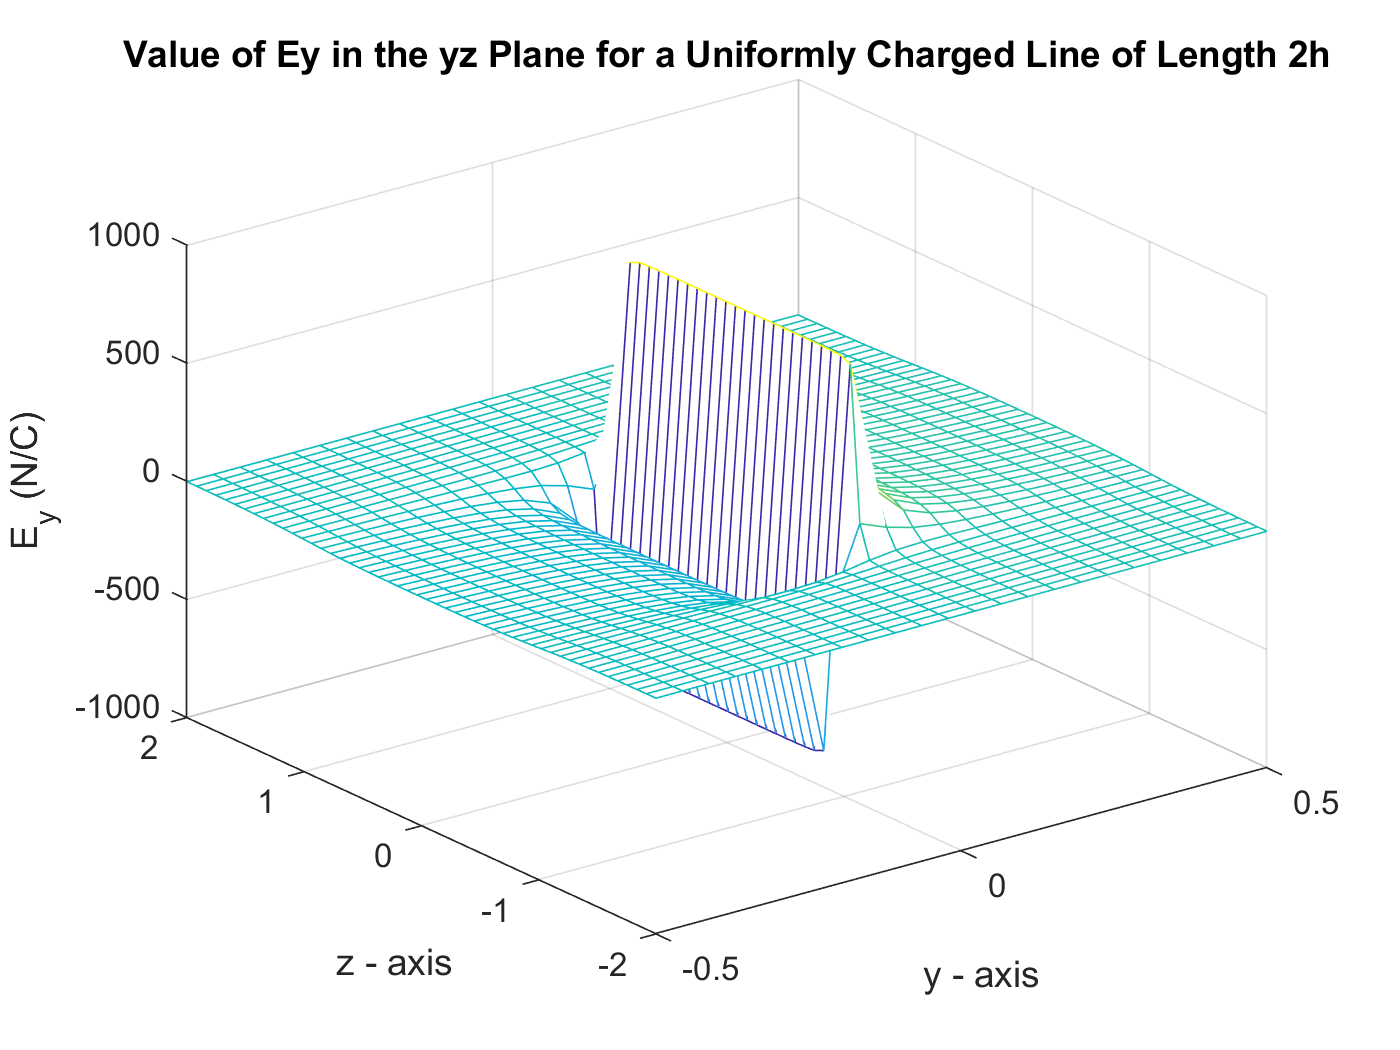

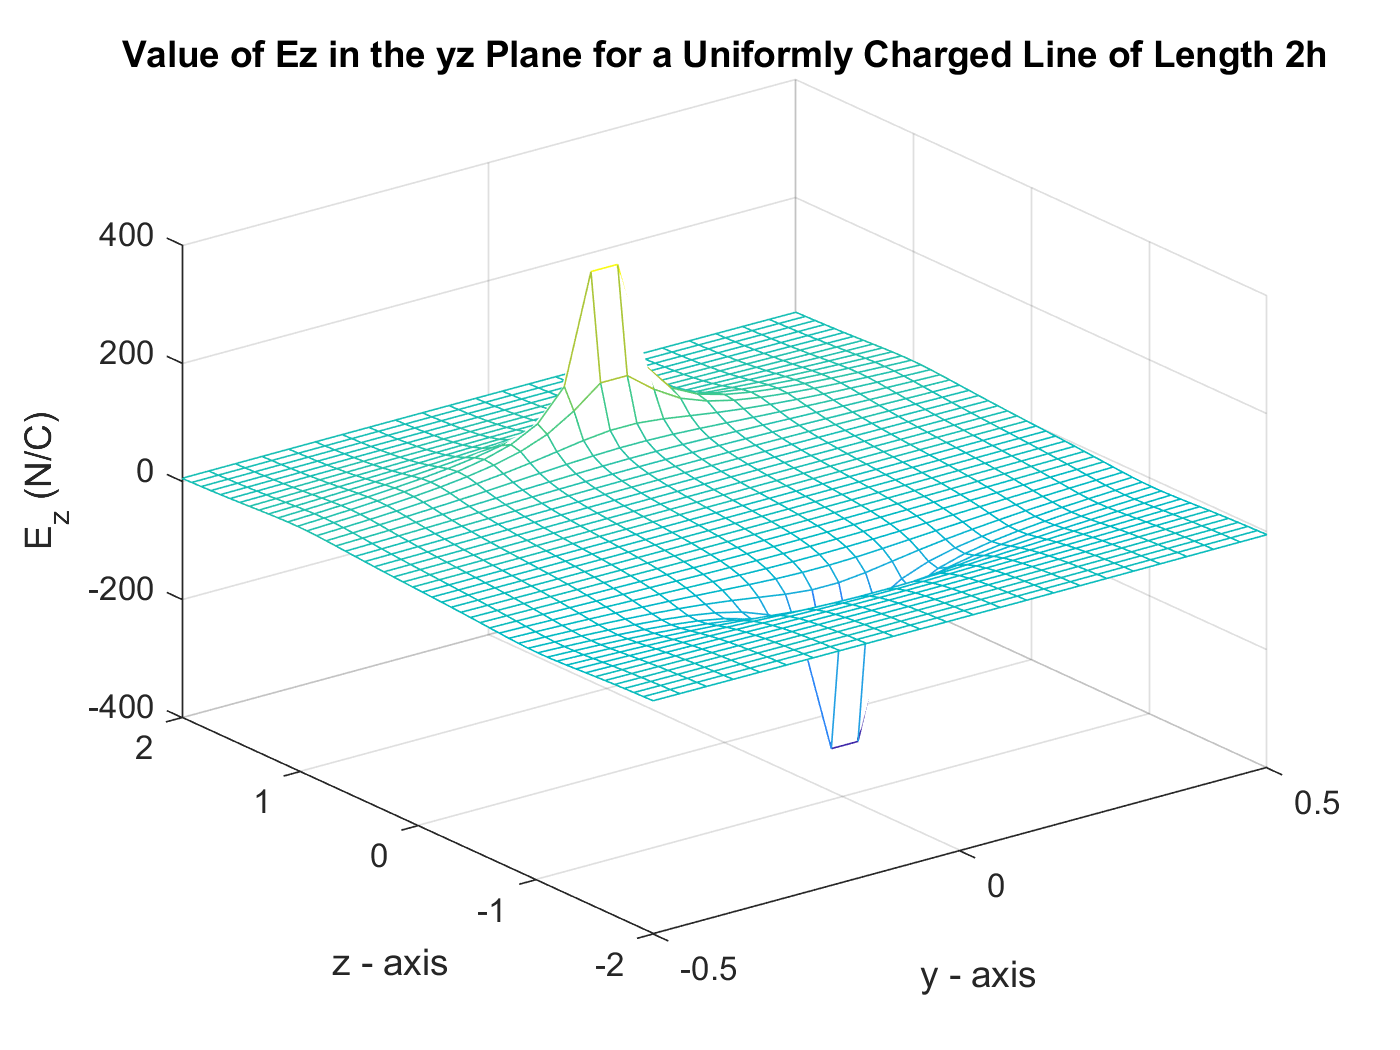

% Author: Shi Jie (Barney) Wei
% Date: 02/01/19

% 1) lineofcharge
h = 1;
rhol = 1e-9;
x = 10;
y = 10;
z = 10;
N = 500;
[Etot, Ex, Ey, Ez] = lineofcharge(h,rhol,x,y,z,N);

% 2) plotlineofcharge
plotlineofcharge(h,rhol,N);

function [Etot,Ex,Ey,Ez]=lineofcharge(h,rhol,x,y,z,N)
    epsilon=8.854e-12;
    dz=2*h/N; % Discretize the total line length of 2h into N pieces
    zprime=linspace(-h,h,N); % The linspace command creates a vector that ranges
    
    % from -h to h and has N elements with equal spacing
    % Use a vectorized approach to "walk" along the line
    integrand=dz./((x^2+y^2+(z-zprime).^2).^(3/2));
    dEx=integrand;
    dEy=integrand;
    dEz=(z-zprime).*integrand;
    
    % Do the "integration" by summing up the differential pieces that result from
    % each value of zprime.
    Ex=((rhol*x)/(4*pi*epsilon))*sum(dEx);
    Ey=((rhol*y)/(4*pi*epsilon))*sum(dEy);
    Ez=(rhol/(4*pi*epsilon))*sum(dEz);
    Etot=(Ex^2+Ey^2+Ez^2)^0.5;
end
function [Etot,Ex,Ey,Ez]=plotlineofcharge(h,rhol,N)
    x=0; % We will focus on the fields in the yz plane
    y=linspace(-0.5,0.5,24); % These define the y and z values of the
    z=linspace(-2,2,50); % points at which we want to find the fields.
    
    % These for loops calculate the field components at each point of interest
    % in the yz plane. As a result we have matrices that are created, with
    % the rows corresponding to fixed z values, and the columns corresponding
    % to fixed y values.
    for e=1:length(z)
        for m=1:length(y)
            [Etot(e,m),Ex(e,m),Ey(e,m),Ez(e,m)]=lineofcharge(h,rhol,0,y(m),z(e),N);
        end
    end
    
    [Y,Z]=meshgrid(y,z); % Create the required arrays for the 3D plots
    figure % Create a figure for the view of the Ey component of the field
    mesh(Y,Z,Ey);
    xlabel('y - axis');
    ylabel('z - axis');
    zlabel('E_y (N/C)');
    title('Value of Ey in the yz Plane for a Uniformly Charged Line of Length 2h');
    grid on;
    
    figure % Create a figure for the view of the Ez component of the field
    mesh(Y,Z,Ez);
    xlabel('y - axis');
    ylabel('z - axis');
    zlabel('E_z (N/C)');
    title('Value of Ez in the yz Plane for a Uniformly Charged Line of Length 2h');
    grid on;
end